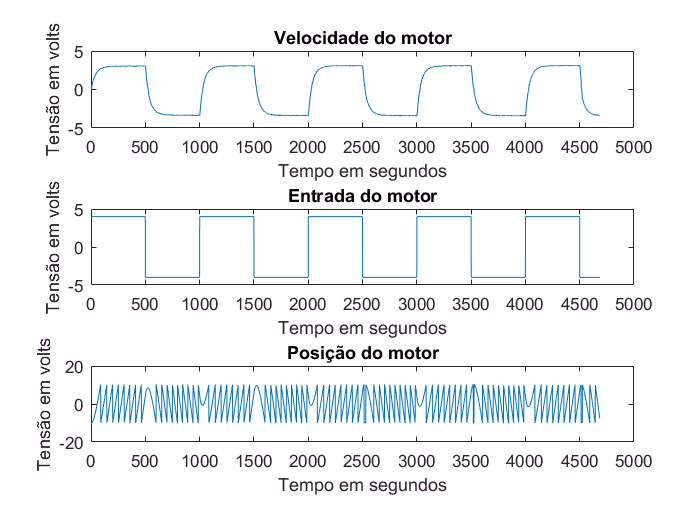

%% Gabriel Cardoso RA: 18.00477-6

clear all;
clc;
close all;

%% Atividade P4

LeituraDados;              %Le os dados do motor


%% Análise dos dados do motor
figure(1)

subplot(3,1,1); plot(vel) % Velocidade
xlabel('Tempo em segundos')
ylabel('Tensão em volts')
title('Velocidade do motor')
subplot(3,1,2); plot(Entrada) % Entrada
xlabel('Tempo em segundos')
ylabel('Tensão em volts')
title('Entrada do motor')
subplot(3,1,3); plot(pod) % Posição
xlabel('Tempo em segundos')
ylabel('Tensão em volts')
title('Posição do motor')

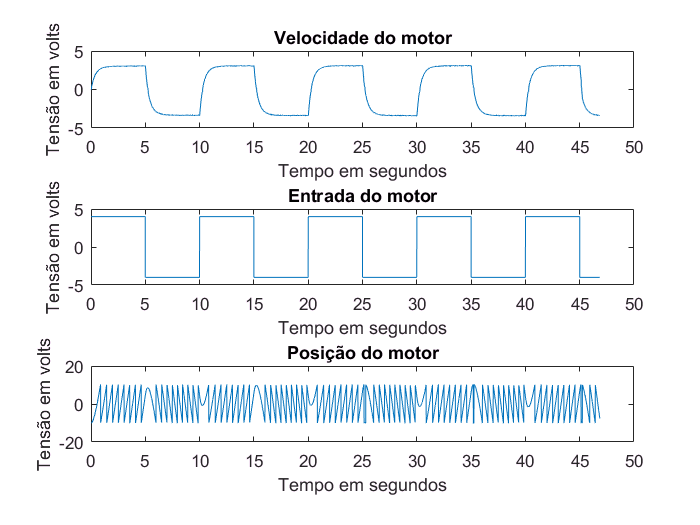

%% Análise do gráfico
N = length(Entrada); % n° de pontos de cada variável
T = 10e-3; % Taxa de amostragem como mostra no gráfico
Duracao = N * T;

tempo = linspace(0,Duracao,N); %vetor tempo
%% Gráfico atualizado
figure(2)

subplot(3,1,1); plot(tempo,vel) % Velocidade
xlabel('Tempo em segundos')
ylabel('Tensão em volts')
title('Velocidade do motor')
subplot(3,1,2); plot(tempo,Entrada) % Entrada
xlabel('Tempo em segundos')
ylabel('Tensão em volts')
title('Entrada do motor')
subplot(3,1,3); plot(tempo,pod) % Posição
xlabel('Tempo em segundos')
ylabel('Tensão em volts')
title('Posição do motor')

%% Modelando o sistema
K = 1; % Hipótese
a = 1;
Gp = K * tf([T 1],[T*a 1]);

ym = lsim(Gp,Entrada,tempo);


figure(3)
plot(tempo,vel);
hold

Current plot held


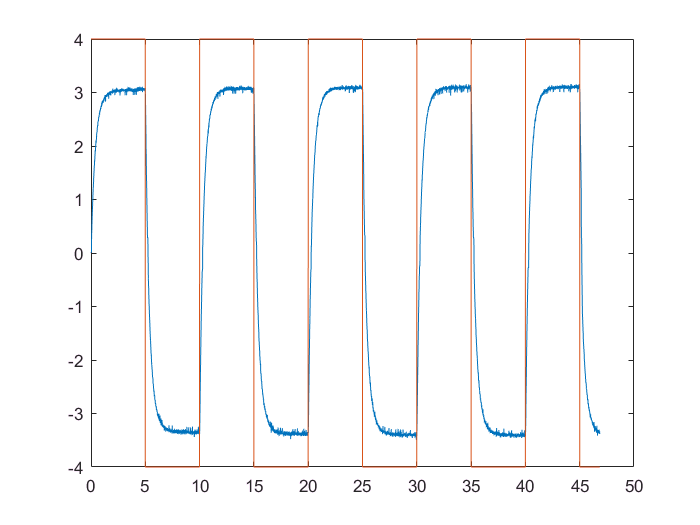

plot(tempo,ym);


%% Determinando K e T visando minimizar o erro
% Quando o ganho é 4 volts velo igual a 3.062
k = 3.062/4

k = 0.7655


Gp = tf(k,[T*a 1]);

ym2 = lsim(Gp,Entrada,tempo);

figure(4)
plot(tempo,vel);
hold

Current plot held


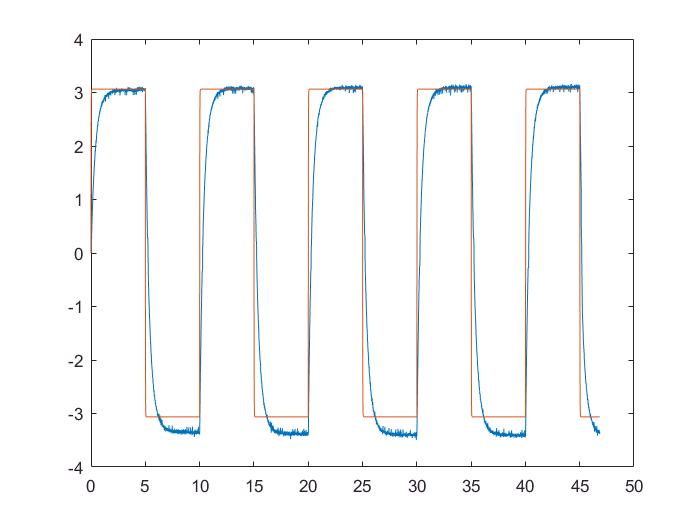

plot(tempo,ym2);


%% Acertando a constante tempo - T-2
% Critério de 2% - 4t

limiar = 0.98* 3.062

limiar = 3.0008


t = 1.66/4; % Tempo em que o sinal atinge 98%

Gp = tf(k,[t 1])


Gp =
 
    0.7655
  -----------
  0.415 s + 1
 
Continuous-time transfer function.




ym3 = lsim(Gp,Entrada,tempo);

figure(5)
plot(tempo,vel);
hold

Current plot held


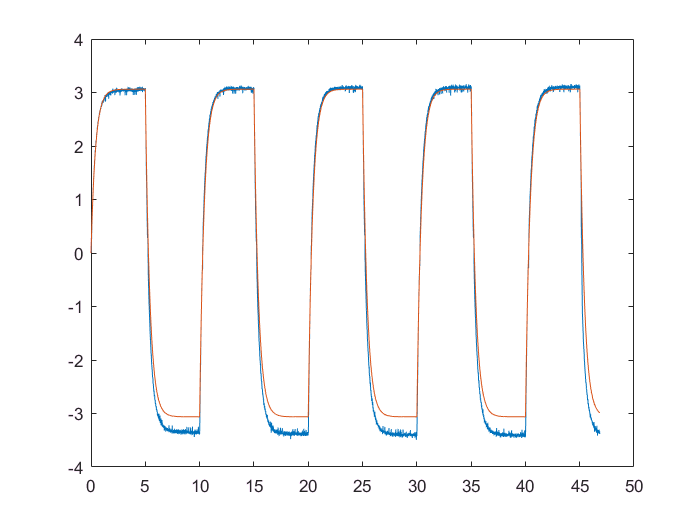

plot(tempo,ym3);


sisotool(Gp)

%% Analisando o sisotool

Gc = tf([7.2 (7.2*2.4)], [1 0])


Gc =
 
  7.2 s + 17.28
  -------------
        s
 
Continuous-time transfer function.



Gma = Gc * Gp


Gma =
 
  5.512 s + 13.23
  ---------------
   0.415 s^2 + s
 
Continuous-time transfer function.




mult = tf([1 0], [1]);
degrau = tf([1], [1 0]);
rampa = tf([1], [1 0 0]);
% Analisando erro ao degrau
syms s
erro_d = mult*(1/(1+Gma))*degrau


erro_d =
 
          0.415 s^3 + s^2
  -------------------------------
  0.415 s^3 + 6.512 s^2 + 13.23 s
 
Continuous-time transfer function.



Erro_d = (0.415*s^3 + s^2)/(0.415*s^3 + 6.512*s^2 + 13.23*s);
limit(Erro_d, s, 0) % Erro igual a 0

$$ans = 0$$

%Analisando erro a rampa 
erro_r = mult*(1/(1+Gma))*rampa


erro_r =
 
           0.415 s^3 + s^2
  ---------------------------------
  0.415 s^4 + 6.512 s^3 + 13.23 s^2
 
Continuous-time transfer function.



Erro_r = (0.415*s^3 + s^2)/(0.415*s^4 + 6.512*s^3 + 13.23*s^2);
limit(Erro_r,s,0)

$$ans = \frac{100}{1323}$$


Gmf = feedback(Gma,1)


Gmf =
 
        5.512 s + 13.23
  ---------------------------
  0.415 s^2 + 6.512 s + 13.23
 
Continuous-time transfer function.



N = [5.512 13.23];

D = [0.415 6.152 13.23];

[Nz Dz] = c2dm(N,D,1);

Gmz = tf(Nz,Dz,1)


Gmz =
 
       1.008 z - 0.0817
  ---------------------------
  z^2 - 0.07353 z + 3.647e-07
 
Sample time: 1 seconds
Discrete-time transfer function.




%% Analisando o G posição
Integrador = tf([1],[1 0]);
Gposicao = Gp * Integrador


Gposicao =
 
     0.7655
  -------------
  0.415 s^2 + s
 
Continuous-time transfer function.



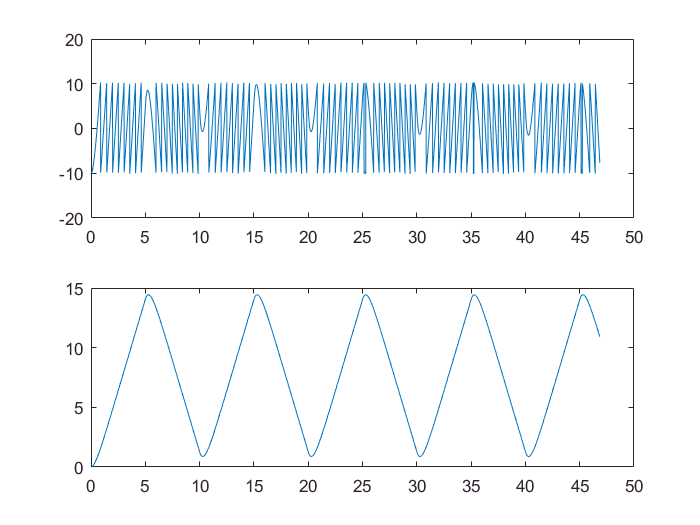


ypos = lsim(Gposicao, Entrada, tempo);

figure(6)

subplot(2,1,1);plot(tempo,pod);

subplot(2,1,2);plot(tempo,ypos);


% Analisando o sisotool
Gcp = tf([767 (767*2.33)], [1 43.20])


Gcp =
 
  767 s + 1787
  ------------
    s + 43.2
 
Continuous-time transfer function.



Gmap = Gposicao*Gcp


Gmap =
 
          587.1 s + 1368
  ------------------------------
  0.415 s^3 + 18.93 s^2 + 43.2 s
 
Continuous-time transfer function.




%Erro a rampa
erro_r = mult*(1/(1+Gmap))*rampa


erro_r =
 
        0.415 s^4 + 18.93 s^3 + 43.2 s^2
  --------------------------------------------
  0.415 s^5 + 18.93 s^4 + 630.3 s^3 + 1368 s^2
 
Continuous-time transfer function.



Erro_r = (0.415*s^4 + 18.93*s^3 + 43.2*s^2)/(0.415*s^5 + 18.93*s^3 + 630.3*s^3 + 1368*s^2);
limit(Erro_r,s,0)

$$ans = \frac{3}{95}$$


%% Malha fechada de posição
Gpmf = feedback(Gmap,1)


Gpmf =
 
              587.1 s + 1368
  --------------------------------------
  0.415 s^3 + 18.93 s^2 + 630.3 s + 1368
 
Continuous-time transfer function.




N = [587.1 1368];

D = [0.415 18.93 630.3 1368];

[Nz Dz] = c2dm(N,D,1);

Gmpz = tf(Nz,Dz,1)


Gmpz =
 
       1.008 z - 0.0817
  ---------------------------
  z^2 - 0.07353 z + 3.647e-07
 
Sample time: 1 seconds
Discrete-time transfer function.

